# **Análise e Modelagem de Sistemas Dinâmicos - 2023/2**

## Nome: Thamya Vieira Hashimoto Donadia 

## Data limite para entrega: 25/10/2023

### A entrega deverá ser feita pelo Google ClassRoom

# Trabalho 2 - Sistemas no Espaço de Estados e Linearização

I = 17;          % Seu número I
init_t2(I);     % Define as variaveis dos modelos
datetime('now')

ans = datetime
   27-Oct-2023 19:14:56


## Linearização do Modelo de Válvula Carretel (Spool Valve)

O vídeo abaixo mostra o funcionamento de uma válvula carretel de 4 vias.

%ShowVideo; % Este código pode ser comentado (o vídeo é apenas para ilustrar o funcionamento da válvula)

A Figura abaixo mostra o esquemático de uma válvula carretel de três vias empregada para controlar a vazão em um sistema hidráulico, cujo funcionamento é semelhante à válvula carretel mostrada no vídeo acima.

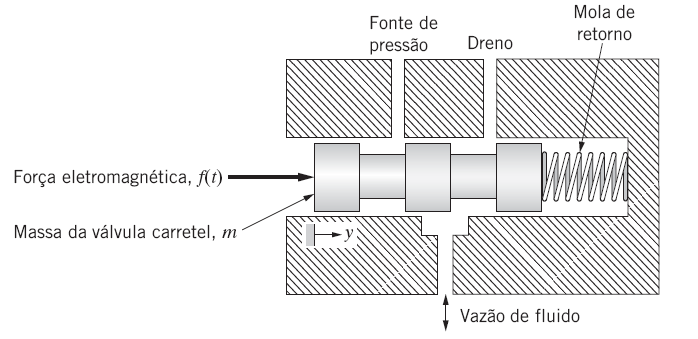

O modelo matemático da válvula carretel consiste em uma única massa ($m\;\left\lbrack \textrm{kg}\right\rbrack$), uma força de atrito linear ($b\;\left\lbrack N\ldotp s/m\right\rbrack$) e uma força de mola linear ($k\;\left\lbrack N/m\right\rbrack$). A variável $y\left(t\right)$ é de deslocamento da válvula carretel (em $\left\lbrack m\right\rbrack$) e $f\left(t\right)$ é a força de um atuador eletromagnético que empurra a válvula (em $\left\lbrack N\right\rbrack$). Assume-se que não existe desequilíbrio na pressão do fluido hidráulico sobre a massa da válvula, e que as forças de fluxo são desprezadas; assim, a força do atuador $f\left(t\right)$ é a única aplicada sobre a massa da válvula. O sistema inicialmente está em repouso (${\dot{y} }_0 =y_0 =0$) no instante $t=0\;\left\lbrack s\right\rbrack$.

**Funções úteis do Matlab:** tf, step, stepDataOptions, lsim, figure, plot, grid, yyaxis, title, xlabel, ylabel, sprintf, linspace.

### 1.1 Usanto o simulink, elabore um diagrama de blocos do modelo dinâmico da válvula (Equação Diferencial) e simule para uma força que varia de $f_{\textrm{inicial}} \;\left\lbrack N\right\rbrack$ a $f_{\textrm{final}} \;\left\lbrack N\right\rbrack$ no instante $t_{\textrm{inicial}} \;\left\lbrack s\right\rbrack$.

**OBS: **

**1) A saída do modelo deve ser um conector do tipo "Out1" disponível na biblioteca "Sinks". **

**2) Escolha um tempo de simulação de aproximadamente 0,1[s] de operação em regime permanente.**

Aplicando a Segunda Lei de Newton, obtemos a modelagem do sistema indicado: 


$$m\ddot{y} \left(t\right)=f\left(t\right)-\textrm{ky}\left(t\right)-b\dot{y} \left(t\right)\;\;\left(1\ldotp 1\right)$$
 

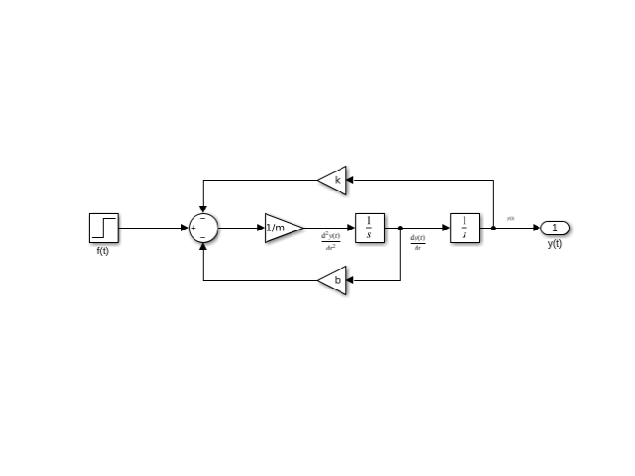

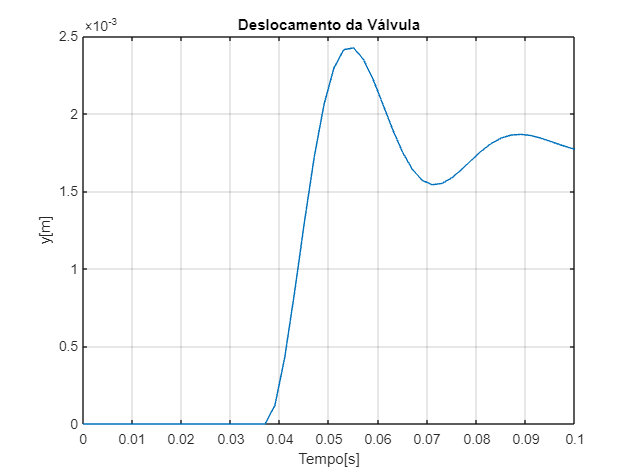

% Modelo original
modelo = 'Questao1_1';
[y1,t1] = snapshotModel(modelo);

### 1.2 Considere que, por desgaste, uma força de atrito seco $f_s \left(t\right)$ passe a compor o atrito da válvula juntamente com o atrito viscoso pré existente. A equação do atrito seco possui uma componente $f_a \left(t\right)$que atua em sentido contrário ao movimento, como mostrado abaixo. 

### 
$$f_s \left(t\right)=f_a \left(t\right)\frac{\dot{y} \left(t\right)}{\left|\dot{y} \left(t\right)\right|}\;\left\lbrack N\right\rbrack$$


### a) É possível simular (no simulink) o modelo com a não linearidade acima? Explique.

A não linearidade *on-off *apresentada acima não pode ser simulada no simulink, em virtude da descontinuidade em $\dot{y} \left(t\right)=0$. Para trabalhar com esse tipo de função, é necessário um pequeno intervalo de integração, permitindo que a força seja calculada com precisão ao se aproximar da velocidade nula. Isso faz com que o tempo de execução da simulação seja muito longo, inviabilizando o seu uso no simulink.

### b) Se a afirmativa anterior for verdadeira, simule, no simulink, para uma força que varia de $f_{\textrm{inicial}} \;\left\lbrack N\right\rbrack$ a $f_{\textrm{final}} \;\left\lbrack N\right\rbrack$ no instante $t_{\textrm{inicial}} \;\left\lbrack s\right\rbrack$. Senão, estabeleça uma forma de modelar a não linearidade e simule para as mesmas condições.

**OBS: **

**1) A saída do modelo deve ser um conector do tipo "Out1" disponível na biblioteca "Sinks". **

**2) Escolha um tempo de simulação de aproximadamente 0,1[s] de operação em regime permanente.**

O atrito seco pode ser aproximado por: 

$f_s \left(t\right)=f_a \left(t\right)*\frac{\left(\dot{y} \left(t\right)\right)}{\sqrt{{\dot{y} }^2 \left(t\right)+\mu^2 \;}}$, tal que $\mu \cong {10}^{-4} \;\left\lbrack \frac{m}{s}\right\rbrack$

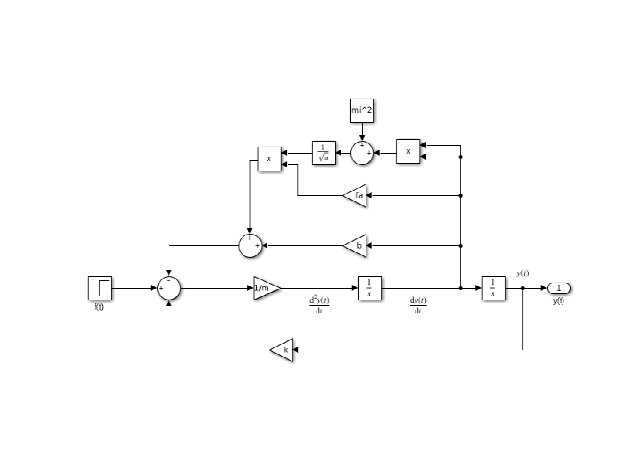

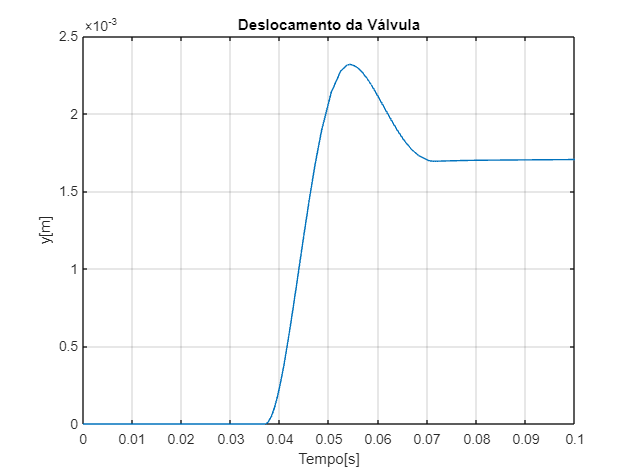

% Modelo linearizado
mi = 10^(-4);
modelo = 'Questao1_2';
[y2,t2] = snapshotModel(modelo);

### c) Compare a resposta da válvula sem o atrito seco com a resposta com o atrito seco linearizado.

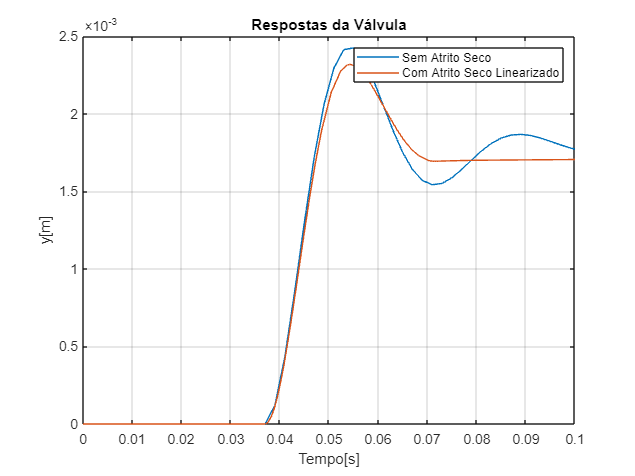

% Gráficos para comparação
figure;
plot(t1,y1)
hold on
plot(t2,y2)
grid on
legend('Sem Atrito Seco','Com Atrito Seco Linearizado')
xlabel('Tempo[s]')
ylabel('y[m]')
title('Respostas da Válvula')

A partir dos gráficos obtidos, foi possível observar que, com a força de atrito seco compondo o atrito da válvula, juntamente com o atrito viscoso pré existente, a oscilação da válvula reduziu. Dessa forma, após a variação da força de entrada, no tempo t_inicial (0.0370s), a válvula apresentou maior estabilidade em seu deslocamento, isto é mais amortecido, comparado ao movimento sem o atrito seco.

## Análise dos Estados de um Conjunto de Vagões Interligados

A Figura abaixo mostra um conjunto de três vagões interligados. A ligação entre eles pode ser modelada como um par mola-amortecedor. A motorização do comboio é feita no vagão de trás, gerando uma força $u_1(t)$, enquanto a frenagem é feita no vagão da frente, gerando uma força $u_2(t)$. A posição dos vagões é obtida a partir de um ponto de referência O, sendo que o vagão 1 inicia a uma distancia $L_1$ de O. As distâncias $L_2$ e $L_3$ são tais que os conjuntos mola-amortecedor encontram-se em repouso.

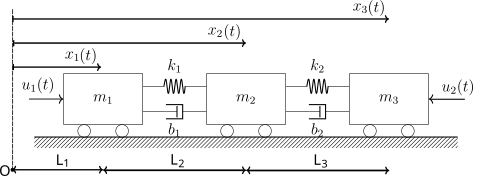

### 2.1 Considere as posições $x_1(t)$, $x_2(t)$, $x_3(t)$, e as velocidades $\dot{x}_1(t)$, $\dot{x}_2(t)$, $\dot{x}_3(t)$, como estados. O modelo em espaço de estados será linear? Justifique sua resposta.

O modelo não será linear, uma vez que apresentará uma componente constante, causada pela distância dos vagões em relação ao ponto de referência, quando os conjuntos mola-amortecedor encontram-se em repouso. Dessa forma, a função é classificada como afim, e, portanto, o sistema é não linear.

### 2.2 Represente o modelo do sistema no Espaço de Estados (linearize o sistema, caso seja necessário), sendo $u_1(t)$ e $u_2(t)$ as entradas e, as posições de cada vagão, as saídas.

A priori, considere $x_{3\;} \left(t\right)>x_{2\;} \left(t\right){\;>x}_{1\;} \left(t\right)>0\;$. Assim, analisando o vagão de massa $m_1$, aplicando a Segunda Lei de Newton, obtemos


$$\left.m_1 \ddot{x_1 \left(\right.} t\right)=k_1 \left(\left({\;x}_2 \left(t\right)-x_1 \left(t\right)\right)-L_2 \right)+b_1 \left(\dot{x_2 } \left(t\right)-\dot{x_1 } \left(t\right)\right)+\;u_1 \left(t\right)\;\left(2\ldotp 1\right)$$


Analisando o vagão de massa $m_2$, aplicando a Segunda Lei de Newton, obtemos


$$\left.m_2 \ddot{x_2 \left(\right.} t\right)=-k_1 \left(\left({\;x}_2 \left(t\right)-x_1 \left(t\right)\right)-L_2 \right)-b_1 \left(\dot{x_2 } \left(t\right)-\dot{x_1 } \left(t\right)\right)+\;k_2 \left(\left(x_3 \left(t\right)-x_2 \left(t\right)\right)-L_3 \right)+b_2 \left(\dot{x_3 } \left(t\right)-\dot{x_2 } \left(t\right)\right)\;\left(2\ldotp 2\right)$$


Analisando o vagão de massa $m_3$, aplicando a Segunda Lei de Newton, obtemos


$$\left.m_3 \ddot{x_3 \left(\right.} t\right)=-k_2 \left(\left(x_3 \left(t\right)-x_2 \left(t\right)\right)-L_3 \right)-b_2 \left(\dot{x_3 } \left(t\right)-\dot{x_2 } \left(t\right)\right)-u_2 \left(t\right)\;\left(2\ldotp 3\right)$$


Considere os estados: $q_1 \left(t\right)=x_1 \left(t\right),\;q_2 \left(t\right)=x_2 \left(t\right),\;q_3 \left(t\right)=x_3 \left(t\right),\;q_4 \left(t\right)=\dot{x_1 } \left(t\right),{\;q}_5 \left(t\right)=\dot{x_2 } \left(t\right),\;q_6 \left(t\right)=\dot{x_3 } \left(t\right)$. Dessa forma, o modelo em Espaço de Estados é dado por


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{q_1 } \left(t\right)\\
\dot{q_2 } \left(t\right)\\
\dot{q_3 } \left(t\right)\\
\dot{q_4 } \left(t\right)\\
\dot{q_5 } \left(t\right)\\
\dot{q_6 } \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
f_1 \left(\mathit{\mathbf{q}},\mathit{\mathbf{u}}\right)\\
f_2 \left(\mathit{\mathbf{q}},\mathit{\mathbf{u}}\;\right)\\
f_3 \left(\mathit{\mathbf{q}},\mathit{\mathbf{u}}\right)\\
f_4 \left(\mathit{\mathbf{q}},\mathit{\mathbf{u}}\right)\\
f_5 \left(\mathit{\mathbf{q}},\mathit{\mathbf{u}}\right)\\
f_6 \left(\mathit{\mathbf{q}},\mathit{\mathbf{u}}\right)
\end{array}\right\rbrack \\
\Rightarrow \left\lbrack \begin{array}{c}
\dot{q_1 } \left(t\right)\\
\dot{q_2 } \left(t\right)\\
\dot{q_3 } \left(t\right)\\
\dot{q_4 } \left(t\right)\\
\dot{q_5 } \left(t\right)\\
\dot{q_6 } \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
q_4 \left(t\right)\\
q_5 \left(t\right)\\
q_6 \left(t\right)\\
-\frac{k_1 }{m_1 }L_2 +\frac{k_1 }{m_1 }q_2 \left(t\right)-\frac{k_1 }{m_1 }q_1 \left(t\right)+\frac{b_1 }{m_1 }q_5 \left(t\right)-\frac{b_1 }{m_1 }q_4 \left(t\right)+\frac{u_1 \left(t\right)}{m_1 }\\
\frac{k_1 }{m_2 }L_2 -\frac{k_1 }{m_2 }q_2 \left(t\right)+\frac{k_1 }{m_2 }q_1 \left(t\right)-\frac{b_1 }{m_2 }q_5 \left(t\right)+\frac{b_1 }{m_2 }q_4 \left(t\right)-\frac{{\;\;k}_2 }{m_2 }L_3 +\frac{{\;\;k}_2 }{m_2 }\;q_3 \left(t\right)-\frac{{\;\;k}_2 }{m_2 }q_2 \left(t\right)\;+\frac{b_2 }{m_2 }q_6 \left(t\right)-\frac{b_2 }{m_2 }q_5 \left(t\right)\\
\;\frac{{\;\;k}_2 }{m_3 }L_3 -\frac{{\;\;k}_2 }{m_3 }\;q_3 \left(t\right)+\frac{{\;\;k}_2 }{m_3 }q_2 \left(t\right)\;-\;\frac{b_2 }{m_3 }q_6 \left(t\right)+\frac{b_2 }{m_3 }q_5 \left(t\right)-\;\frac{u_2 \left(t\right)}{m_3 }
\end{array}\right\rbrack 
\end{array}$$
 


$$\mathit{\mathbf{y}}\left(\mathit{\mathbf{t}}\right)=\;\left\lbrack \begin{array}{c}
y_1 \left(t\right)\\
y_2 \left(t\right)\\
y_3 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
1 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
q_1 \left(t\right)\\
q_2 \left(t\right)\\
q_3 \left(t\right)\\
q_4 \left(t\right)\\
q_5 \left(t\right)\\
{\;q}_6 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \left(t\right)\\
u_2 \left(t\right)
\end{array}\right\rbrack$$


Os pontos de equilíbrio são obtidos para ${\dot{\mathit{\mathbf{q}}} }^* =f\left({\mathit{\mathbf{q}}}^* ,{\mathit{\mathbf{u}}}^* \right)=0$. Do enunciado, temos que, quando os conjuntos mola-amortecedor estão em repouso, isto é, quando o sistema encontra-se em equilíbrio, os vagões $m_1 ,m_2 ,m_3$ estão a uma distância de $L_1 ,L_1 +L_2 ,L_1 +L_2 +L_3$, respectivamente, do ponto de referência. Assim, temos que $q_1^* =L_1 ,\;q_2^* =L_1 +L_2 ,{\;q}_3^* =L_1 +L_{2\;} +L_3$. Substituindo tais valores nas equações ${\dot{\mathit{\mathbf{q}}} }^* =f\left({\mathit{\mathbf{q}}}^* ,{\mathit{\mathbf{u}}}^* \right)=0$, obtemos:  


$$\left\lbrack \begin{array}{c}
f_1 \left(\mathit{\mathbf{q}}\right)\\
f_2 \left(\mathit{\mathbf{q}}\right)\\
f_3 \left(\mathit{\mathbf{q}}\right)\\
f_4 \left(\mathit{\mathbf{q}}\right)\\
f_5 \left(\mathit{\mathbf{q}}\right)\\
f_6 \left(\mathit{\mathbf{q}}\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack \Rightarrow \left\lbrace \begin{array}{l}
q_1^* =L_1 \\
q_2^* =L_1 +L_2 \\
{\;q}_3^* =L_1 +L_{2\;} +L_3 \\
q_4^* =\;q_5^* =q_6^* =0\\
u_1^* =u_2^* =0
\end{array}\right\rbrace \;$$


Seja $\dot{\mathit{\mathbf{z}}} =\mathit{\mathbf{q}}-{\mathit{\mathbf{q}}}^*$,  $\dot{\mathit{\mathbf{v}}} =\mathit{\mathbf{u}}-{\mathit{\mathbf{u}}}^*$, para o sistema linearizado, temos


$$\dot{\mathit{\mathbf{z}}} =\mathbf{Az}+\mathbf{Bv}=\;\left\lbrack \begin{array}{cccccc}
\frac{\partial }{\partial q_1 }f_1  & \frac{\partial }{\partial q_2 }f_1  & \frac{\partial }{\partial q_3 }f_1  & \frac{\partial }{\partial q_4 }f_1  & \frac{\partial }{\partial q_5 }f_1  & \frac{\partial }{\partial q_6 }f_1 \\
\frac{\partial }{\partial q_1 }f_2  & \frac{\partial }{\partial q_2 }f_2  & \frac{\partial }{\partial q_3 }f_2  & \frac{\partial }{\partial q_4 }f_2  & \frac{\partial }{\partial q_5 }f_2  & \frac{\partial }{\partial q_6 }f_2 \\
\frac{\partial }{\partial q_1 }f_3  & \frac{\partial }{\partial q_2 }f_2  & \frac{\partial }{\partial q_3 }f_3  & \frac{\partial }{\partial q_4 }f_3  & \frac{\partial }{\partial q_5 }f_3  & \frac{\partial }{\partial q_6 }f_3 \\
\frac{\partial }{\partial q_1 }f_4  & \frac{\partial }{\partial q_2 }f_4  & \frac{\partial }{\partial q_3 }f_4  & \frac{\partial }{\partial q_4 }f_4  & \frac{\partial }{\partial q_5 }f_4  & \frac{\partial }{\partial q_6 }f_4 \\
\frac{\partial }{\partial q_1 }f_5  & \frac{\partial }{\partial q_2 }f_5  & \frac{\partial }{\partial q_3 }f_5  & \frac{\partial }{\partial q_4 }f_5  & \frac{\partial }{\partial q_5 }f_5  & \frac{\partial }{\partial q_6 }f_5 \\
\frac{\partial }{\partial q_1 }f_6  & \frac{\partial }{\partial q_2 }f_6  & \frac{\partial }{\partial q_3 }f_6  & \frac{\partial }{\partial q_4 }f_6  & \frac{\partial }{\partial q_5 }f_6  & \frac{\partial }{\partial q_6 }f_6 
\end{array}\right\rbrack \;\left\lbrack \begin{array}{c}
z_1 \left(t\right)\\
z_2 \left(t\right)\\
z_3 \left(t\right)\\
z_4 \left(t\right)\\
z_5 \left(t\right)\\
{\;z}_6 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
\frac{\partial }{\partial u_1 }f_1  & \frac{\partial }{\partial u_2 }f_2 \\
\frac{\partial }{\partial u_1 }f_2  & \frac{\partial }{\partial u_2 }f_2 \\
\frac{\partial }{\partial u_1 }f_3  & \frac{\partial }{\partial u_2 }f_3 \\
\frac{\partial }{\partial u_1 }f_4  & \frac{\partial }{\partial u_2 }f_4 \\
\frac{\partial }{\partial u_1 }f_5  & \frac{\partial }{\partial u_2 }f_5 \\
\frac{\partial }{\partial u_1 }f_6  & \frac{\partial }{\partial u_2 }f_6 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_1 \left(t\right)\\
v_2 \left(t\right)
\end{array}\right\rbrack \;\;$$


Substituindo $\mathit{\mathbf{q}}={\mathit{\mathbf{q}}}^* e\;\mathit{\mathbf{u}}={\mathit{\mathbf{u}}}^*$: 


$$\left\lbrack \begin{array}{c}
\dot{z_1 } \left(t\right)\\
\dot{z_2 } \left(t\right)\\
\dot{z_3 } \left(t\right)\\
\dot{z_4 } \left(t\right)\\
\dot{z_5 } \left(t\right)\\
\dot{z_6 } \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
-\frac{k_1 }{m_1 } & \frac{k_1 }{m_1 } & 0 & -\frac{b_1 }{m_1 } & \frac{b_1 }{m_1 } & 0\\
\frac{k_1 }{m_2 } & -\frac{\left(k_1 +k_2 \right)}{m_2 } & \frac{k_2 }{m_2 } & \frac{b_1 }{m_2 } & -\frac{\left(b_1 +b_2 \right)}{m_2 } & \frac{b_2 }{m_2 }\\
0 & \frac{k_2 }{m_3 } & -\frac{k_2 }{m_3 } & 0 & \frac{b_2 }{m_3 } & -\frac{b_2 }{m_3 }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
z_1 \left(t\right)\\
z_2 \left(t\right)\\
z_3 \left(t\right)\\
z_4 \left(t\right)\\
z_5 \left(t\right)\\
{\;z}_6 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0\\
\frac{1}{m_1 } & 0\\
0 & 0\\
0 & -\frac{1}{m_3 }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_1 \left(t\right)\\
v_2 \left(t\right)
\end{array}\right\rbrack$$


Assim, tomando o ponto de equilíbrio, o sistema $\dot{\mathit{\mathbf{q}}} \left(\mathit{\mathbf{t}}\right)=\textrm{Aq}\left(\mathit{\mathbf{t}}\right)+\textrm{Bu}\left(\mathit{\mathbf{t}}\right),\mathit{\mathbf{y}}\left(\mathit{\mathbf{t}}\right)=\textrm{Cq}\left(\mathit{\mathbf{t}}\right)+\textrm{Du}\left(\mathit{\mathbf{t}}\right)$ é dado por: 


$$\left\lbrack \begin{array}{c}
\dot{q_1 } \left(t\right)\\
\dot{q_2 } \left(t\right)\\
\dot{q_3 } \left(t\right)\\
\dot{q_4 } \left(t\right)\\
\dot{q_5 } \left(t\right)\\
\dot{q_6 } \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
-\frac{k_1 }{m_1 } & \frac{k_1 }{m_1 } & 0 & -\frac{b_1 }{m_1 } & \frac{b_1 }{m_1 } & 0\\
\frac{k_1 }{m_2 } & -\frac{\left(k_1 +k_2 \right)}{m_2 } & \frac{k_2 }{m_2 } & \frac{b_1 }{m_2 } & -\frac{\left(b_1 +b_2 \right)}{m_2 } & \frac{b_2 }{m_2 }\\
0 & \frac{k_2 }{m_3 } & -\frac{k_2 }{m_3 } & 0 & \frac{b_2 }{m_3 } & -\frac{b_2 }{m_3 }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
q_1 \left(t\right)-\;L_1 \\
q_2 \left(t\right)-\left(L_1 +L_2 \right)\\
q_3 \left(t\right)-\left({L_1 +L_2 +\;L}_3 \right)\\
q_4 \left(t\right)\\
q_5 \left(t\right)\\
{\;q}_6 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0\\
\frac{1}{m_1 } & 0\\
0 & 0\\
0 & -\frac{1}{m_3 }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \left(t\right)\\
u_2 \left(t\right)
\end{array}\right\rbrack$$



$$\mathit{\mathbf{y}}\left(\mathit{\mathbf{t}}\right)=\;\left\lbrack \begin{array}{c}
y_1 \left(t\right)\\
y_2 \left(t\right)\\
y_3 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
1 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
q_1 \left(t\right)\\
q_2 \left(t\right)\\
q_3 \left(t\right)\\
q_4 \left(t\right)\\
q_5 \left(t\right)\\
{\;q}_6 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \left(t\right)\\
u_2 \left(t\right)
\end{array}\right\rbrack$$


% Modelo no Espaço de Estados
A = [  0      0         0       1      0          0;
       0      0         0       0       1         0;
       0      0         0       0       0         1;
      -k1/m1  k1/m1     0    -b1/m1   b1/m1       0;
       k1/m2 -(k1+k2)/m2 k2/m2 b1/m2 -(b1+b2)/m2 b2/m2;
      0      k2/m3     -k2/m3   0     b2/m3     -b2/m3;
     ];

B = [ 0   0;
      0   0; 
      0   0;
     1/m1 0;
      0   0; 
      0 -1/m3;
     ];

C = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 1 0 0 0;
    ];

D = [0 0; 
     0 0;
     0 0; 
    ];

sistema = ss(A, B, C, D);

### 2.2 Obtenha a resposta $y(t)$ do sistema para entradas tipo impulso unitário: 

### a) apenas para a entrada $u_1(t) = \delta(t)$; 

### b) apenas para a entrada $u_2(t) = \delta(t)$; 

### c) para entradas $u_1(t) = u_2(t) = \delta(t)$. 

### Apresente a resposta até 20 segundos. Unidades em SI.

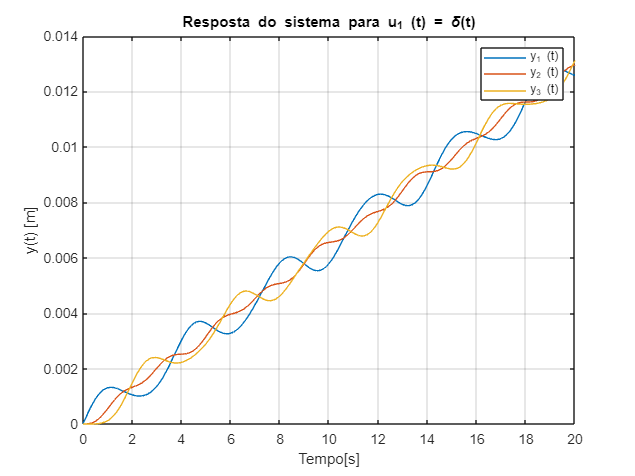

% Gráficos da Resposta
s = tf('s');
vetor_tempo = 0:0.1:20; % Vetor de 0 a 20 segundos
I = eye(size(A)); % Matriz identidade 6x6

% Matriz de Funções de Transferência do sistema em EE
G = C*inv((s*I- (A)))*B + D; % Matriz 3x2

% a) Resposta y(t) para apenas para entrada u1(t)

% Obtendo as saídas 1, 2 e 3 do sistema para u1(t) = impulso unitário,  a
% partir das funções de transferência que relacionam a entrada 1 com as saídas
[y1_1, vetor_tempo] = impulse(G(1, 1), vetor_tempo);
[y2_1, vetor_tempo] = impulse(G(2, 1), vetor_tempo);
[y3_1, vetor_tempo] = impulse(G(3, 1), vetor_tempo);

% Plotando a resposta obtida 
figure;  plot(vetor_tempo, y1_1)
hold on; plot(vetor_tempo, y2_1)
hold on; plot(vetor_tempo, y3_1)
grid on
legend('y_1 (t)  ','y_2 (t)  ', 'y_3 (t)  ')
xlabel('Tempo[s]'); ylabel('y(t) [m]')
title('Resposta do sistema para u_1 (t) = \delta(t)')

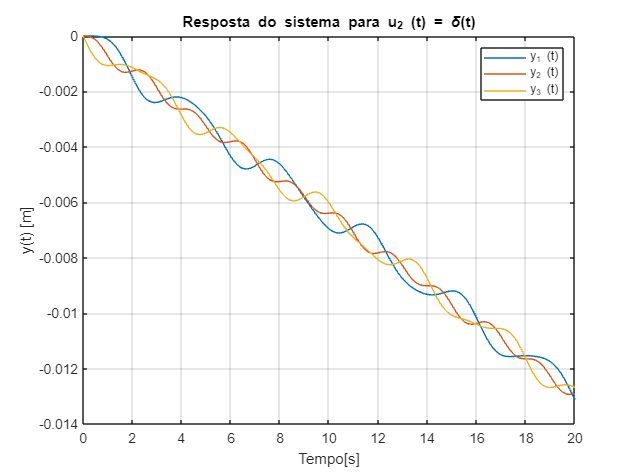

% b) Resposta y(t) para apenas para entrada u2(t)

% Obtendo as saídas 1, 2 e 3 do sistema para u2(t) = impulso unitário,  a
% partir das funções de transferência que relacionam a entrada 2 com as saídas
[y1_2, vetor_tempo] = impulse(G(1, 2), vetor_tempo);
[y2_2, vetor_tempo] = impulse(G(2, 2), vetor_tempo);
[y3_2, vetor_tempo] = impulse(G(3, 2), vetor_tempo);

% Plotando a resposta obtida 
figure;  plot(vetor_tempo, y1_2)
hold on; plot(vetor_tempo, y2_2)
hold on; plot(vetor_tempo, y3_2)
grid on
legend('y_1 (t)  ','y_2 (t)  ', 'y_3 (t)  ')
xlabel('Tempo[s]'); ylabel('y(t) [m]')
title('Resposta do sistema para u_2 (t) = \delta(t)')

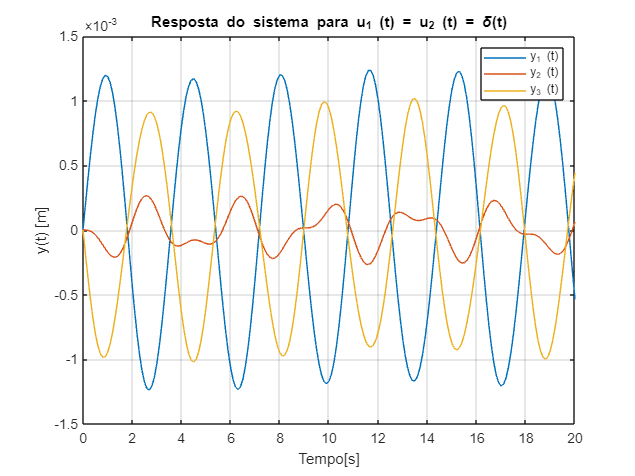

% c) Resposta y(t) para entradas u1(t) = u2(t) = impulso unitário
% Funções de Transferência que relacionam a entrada 1 e 2 com as saídas 1, 2, 3 
G1 = G(1, 1) +  G(1, 2);
G2 = G(2, 1) +  G(2, 2); 
G3 = G(3, 1) +  G(3, 2);

% Obtendo as saídas 1, 2 e 3 do sistema para u1(t) = u2(t) = impulso unitário
[y1_3, vetor_tempo] = impulse(G1, vetor_tempo);
[y2_3, vetor_tempo] = impulse(G2, vetor_tempo);
[y3_3, vetor_tempo] = impulse(G3, vetor_tempo);

% Plotando a resposta obtida 
figure;  plot(vetor_tempo, y1_3)
hold on; plot(vetor_tempo, y2_3)
hold on; plot(vetor_tempo, y3_3)
grid on
legend('y_1 (t)  ','y_2 (t)  ', 'y_3 (t)  ')
xlabel('Tempo[s]'); ylabel('y(t) [m]')
title('Resposta do sistema para u_1 (t) = u_2 (t) = \delta(t)')

### 2.3 Explique o comportamento visto para o caso $u_1(t) = u_2(t) = \delta(t)$.

Neste caso, é possível observar que o movimento da massa $m_2$ é reduzido (amortecido), em função das duas forças iguais de entrada que apresentam mesmo módulo, mas sentidos opostos. Dessa forma, a resposta dos conjuntos amortecedor-mola, em função da força impulso de entada, provoca a redução da oscilação do deslocamento da massa $m_2$